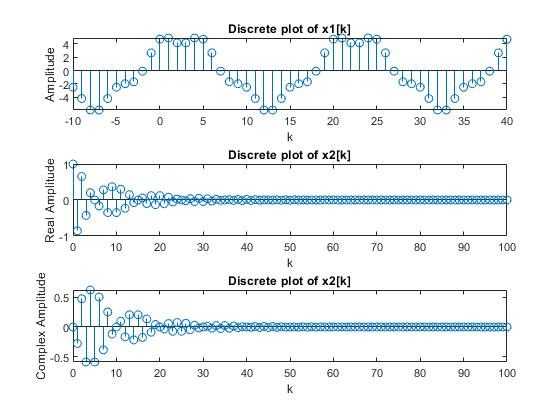

% part 1 
% part a
k1 = (-10:40);
k2 = (0:100);

x1 = -5.1*sin(0.1*pi*k1 - 3*pi/4) + 1.1*cos(0.4*pi*k1);
x2 = (-0.9).^k2 .* (cos(pi.*k2/10)+sin(pi.*k2/10).*1j);

% plots for a
figure('Name', 'Plotting Discrete Functions')
subplot(3, 1, 1)
stem(k1,x1)
title('Discrete plot of x1[k]')
xlabel('k')
ylabel('Amplitude')

subplot(3, 1, 2)
stem(k2, real(x2))
title('Discrete plot of x2[k]')
xlabel('k')
ylabel('Real Amplitude')

subplot(3, 1, 3)
stem(k2, imag(x2))
title('Discrete plot of x2[k]')
xlabel('k')
ylabel('Complex Amplitude')


% part c
fprintf('The energy of x1 is %f.\n', sum(x1.^2));

The energy of x1 is 698.533550.


fprintf('The energy of x2 is %f.\n', sum(abs(x2).^2));

The energy of x2 is 5.263158.



clear

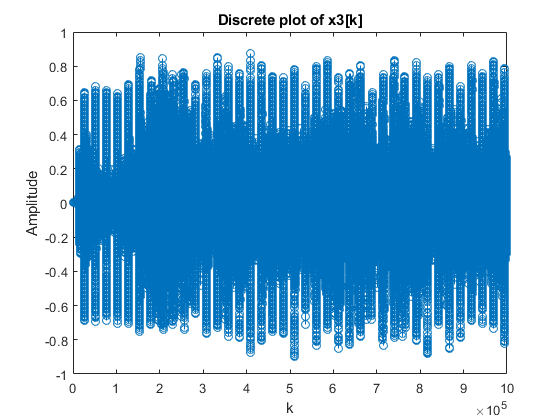

% part 2
% part b
[x3,Fs]  = audioread("baila.wav");
% part c
figure('Name', 'Digital Audio')
subplot(1,1,1)
stem(x3)
title('Discrete plot of x3[k]')
xlabel('k')
ylabel('Amplitude')

% part d
fprintf('The energy of x3 is %f.\n', sum(x3.^2));

The energy of x3 is 20422.773132.


% part e
x3s = x3(1: length(x3)/2);
% part f
audiowrite('baila_half.wav', x3s, Fs)

clear

% part 3
% part b
lena = imread("lena.jpg");
[row, col] = size(lena);
maxpix = max (lena, [], 'all' );
fprintf("Max pixel value is %d\n", maxpix);

Max pixel value is 165

% part c
lena_bright = lena+30;
% part d
imwrite(lena_bright, 'lena_bright.jpg', 'jpg', 'Quality', 100)

clear

% part 4
%part b
u = ones(1,50);
x = (0:49);
figure("name", 'System Response')
subplot(3,1,1)
y1 = sysresp(u, 0.5);
plot(x, y1)
title('Plot of system when a = 0.5')
xlabel('n')
ylabel('y[n] amplitude')
subplot(3,1,2)
y2 = sysresp(u, 2);
plot(x, y2)
title('Plot of system when a = 2')
xlabel('n')
ylabel('y[n] amplitude')

%part c
disp('Another Bibo stable system is when a = 0.6')

Another Bibo stable system is when a = 0.6


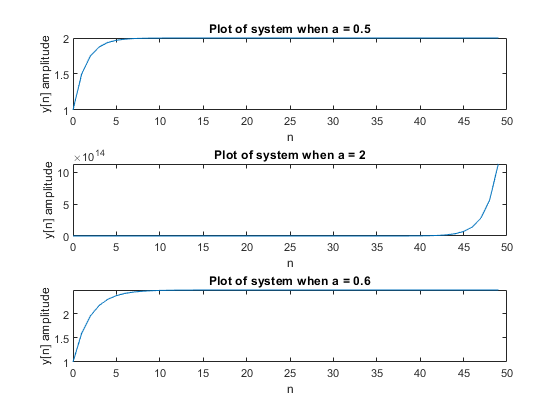

y3 = sysresp(u, 0.6);
subplot(3,1,3)
plot(x, y3)
title('Plot of system when a = 0.6')
xlabel('n')
ylabel('y[n] amplitude')


clear